M = 1000

M = 1000

m1 = 100

m1 = 100

m2 = 100

m2 = 100

l1 = 20

l1 = 20

l2 = 10

l2 = 10

g = 9.8

g = 9.8000

 
 A = [0 1 0 0 0 0 ;
     0 0 ((-m1*g)/M) 0 (-m2*g)/M 0;
     0 0 0 1 0 0;
     0 0 ((-g*(m1+M))/(M*l1)) 0 (-g*(m2)/(M*l1)) 0;
     0 0 0 0 0 1;
     0 0 (-g*(m1))/(M*l2) 0 (-g*(m2+M)/(M*l2)) 0]

A =          0    1.0000         0         0         0         0
         0         0   -0.9800         0   -0.9800         0
         0         0         0    1.0000         0         0
         0         0   -0.5390         0   -0.0490         0
         0         0         0         0         0    1.0000
         0         0   -0.0980         0   -1.0780         0



B = [0; 1/M; 0 ; 1/(M*l1); 0 ; 1/(M*l2)] 

B = 	1.0e+-3 *

         0
    1.0000
         0
    0.0500
         0
    0.1000


C=[1 0 0 0 0 0; 0 0 1 0 0 0; 0 0 0 0 1 0]

C =      1     0     0     0     0     0
     0     0     1     0     0     0
     0     0     0     0     1     0


D = [0; 0; 0]

D =      0
     0
     0



Rank = [B A*B A^2*B A^3*B A^4*B A^5*B]

Rank = 	1.0e+-3 *

         0    1.0000         0   -0.1470         0    0.1417
    1.0000         0   -0.1470         0    0.1417         0
         0    0.0500         0   -0.0319         0    0.0227
    0.0500         0   -0.0319         0    0.0227         0
         0    0.1000         0   -0.1127         0    0.1246
    0.1000         0   -0.1127         0    0.1246         0



states = {'x' 'x_dot' 'theta1' 'theta1_dot' 'theta2' 'theta2_dot'};
inputs = {'u'};
outputs = {'x'; 'theta1'; 'theta2'};

sys_ss = ss(A,B,C,D,'statename',states,'inputname',inputs,'outputname',outputs)


sys_ss =
 
  A = 
                        x       x_dot      theta1  theta1_dot      theta2  theta2_dot
   x                    0           1           0           0           0           0
   x_dot                0           0       -0.98           0       -0.98           0
   theta1               0           0           0           1           0           0
   theta1_dot           0           0      -0.539           0      -0.049           0
   theta2               0           0           0           0           0           1
   theta2_dot           0           0      -0.098           0      -1.078           0
 
  B = 
                    u
   x                0
   x_dot        0.001
   theta1           0
   theta1_dot   5e-05
   theta2           0
   theta2_dot  0.0001
 
  C = 
                    x       x_dot      theta1  theta1_dot      theta2  theta2_dot
   x                1           0           0           0           0           0
   theta1           0           0          


poles = eig(A)

poles =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.7282i
   0.0000 - 0.7282i
   0.0000 + 1.0425i
   0.0000 - 1.0425i


krank=rank(Rank)

krank = 6


Q = (C'*C)

Q =      1     0     0     0     0     0
     0     0     0     0     0     0
     0     0     1     0     0     0
     0     0     0     0     0     0
     0     0     0     0     1     0
     0     0     0     0     0     0


Q(1,1) = 500000

Q =       500000           0           0           0           0           0
           0           0           0           0           0           0
           0           0           1           0           0           0
           0           0           0           0           0           0
           0           0           0           0           1           0
           0           0           0           0           0           0


Q(3,3) = 500

Q =       500000           0           0           0           0           0
           0           0           0           0           0           0
           0           0         500           0           0           0
           0           0           0           0           0           0
           0           0           0           0           1           0
           0           0           0           0           0           0


Q(5,5) = 500

Q =       500000           0           0           0           0           0
           0           0           0           0           0           0
           0           0         500           0           0           0
           0           0           0           0           0           0
           0           0           0           0         500           0
           0           0           0           0           0           0


R = 1;
[K,S,E] = lqr(A,B,Q,R)

K = 	1.0e+03 *

    0.7071    1.2716   -0.3260   -1.0431   -0.2294   -0.6368


S = 	1.0e+07 *

    0.0899    0.0808   -0.0738   -0.0944   -0.0450   -0.0542
    0.0808    0.1575   -0.0383   -0.3203   -0.0268   -0.1433
   -0.0738   -0.0383    1.9747    0.0544   -0.0050    0.0294
   -0.0944   -0.3203    0.0544    4.1693    0.0370    0.0748
   -0.0450   -0.0268   -0.0050    0.0370    0.6963    0.0203
   -0.0542   -0.1433    0.0294    0.0748    0.0203    0.7593


E =   -0.5370 + 0.5890i
  -0.5370 - 0.5890i
  -0.0261 + 1.0256i
  -0.0261 - 1.0256i
  -0.0147 + 0.7125i
  -0.0147 - 0.7125i


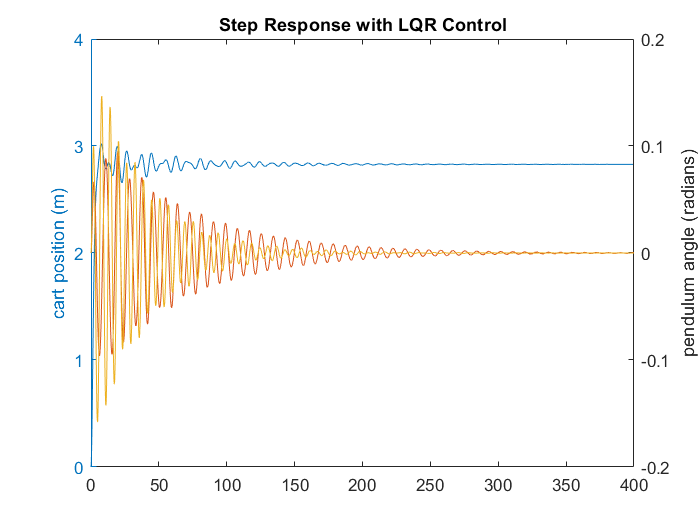

Ac = [(A-B*K)];
Bc = [B];
Cc = [C];
Dc = [D];
states = {'x' 'x_dot' 'theta1' 'theta1_dot' 'theta2' 'theta2_dot'};
inputs = {'r'};
outputs = {'x'; 'theta1' ;'theta2'};
sys_cl = ss(Ac,Bc,Cc,Dc,'statename',states,'inputname',inputs,'outputname',outputs);
t = 0:0.1:400;
r =2000*ones(size(t));
[y,t,x]=lsim(sys_cl,r,t);
[AX,H1,H2] = plotyy(t,y(:,1),[t,t],[y(:,2),y(:,3)],'plot');
set(get(AX(1),'Ylabel'),'String','cart position (m)')
set(get(AX(2),'Ylabel'),'String','pendulum angle (radians)')
title('Step Response with LQR Control')


co=ctrb(sys_ss)

co = 	1.0e+-3 *

         0    1.0000         0   -0.1470         0    0.1417
    1.0000         0   -0.1470         0    0.1417         0
         0    0.0500         0   -0.0319         0    0.0227
    0.0500         0   -0.0319         0    0.0227         0
         0    0.1000         0   -0.1127         0    0.1246
    0.1000         0   -0.1127         0    0.1246         0


controllability = rank(co)

controllability = 6

Eig1=eig(Ac)

Eig1 =   -0.5370 + 0.5890i
  -0.5370 - 0.5890i
  -0.0261 + 1.0256i
  -0.0261 - 1.0256i
  -0.0147 + 0.7125i
  -0.0147 - 0.7125i





p = 10*[Eig1.']

p =   -5.3702 + 5.8897i  -5.3702 - 5.8897i  -0.2614 +10.2555i  -0.2614 -10.2555i  -0.1471 + 7.1249i  -0.1471 - 7.1249i


L=place(A',C',p)'

L =     3.5570    3.2250   -3.7494
   49.2626  -17.8340  -25.5751
    0.8753    2.9707   -0.5552
    7.0149   64.7803  -44.4086
    1.4248    3.6274    5.0297
   42.8041    9.1916   64.8947


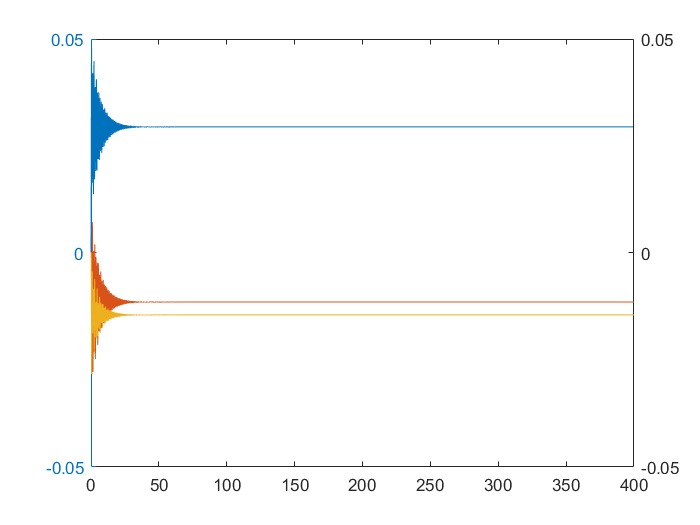

AL= [(A-L*C)];
BL = [B];
CL = [C];
DL = [D];
states = {'x' 'x_dot' 'theta1' 'theta1_dot' 'theta2' 'theta2_dot'};
inputs = {'r'};
outputs = {'x'; 'theta1' ;'theta2'};
sys_cl = ss(AL,BL,CL,DL,'statename',states,'inputname',inputs,'outputname',outputs);
t = 0:0.1:400;
r =2000*ones(size(t));
[y,t,x]=lsim(sys_cl,r,t);
[AX,H1,H2] = plotyy(t,y(:,1),[t,t],[y(:,2),y(:,3)],'plot');